# Complex data import

**Note: A data import as shown here (and formerly in the previous drEEM versions) is not recommended and not supported with toolbox methods. We strongly recommend storing and importing file triplets for every sample (e.g. samplename - sample.csv; samplename - blank.csv; samplename - absorbance.csv). **

## Toolobox setup

First, we initiate this session by clearing all variables, closing all figures, and assigning an object to the toolbox class so we can access it. Then we change to the directory

clearvars
close all
tbx=drEEMtoolbox;
cd(fileparts(matlab.desktop.editor.getActiveFilename))
cd demofiles_complexOrg\

## File importing

Next, all files will get imported. This is relatively straightforward and mostly works with default options, but we have to provide exciation wavlengths for the EEMs (they were not included in the header) and specify where the absorbance wavelength and absorbance information is located (column number).

Expecially for the EEMs without excitation information in the files, please beware of the order. Here, the exciation columns are ordered increasing, but sometimes they are ordered decreasing (as measured). The EEMs will look strange if you provide the walvenegths in the wrong order.

cd samples
samples=tbx.importeems('*.dat','columnIsExcitation',true,'columnWave',240:10:450);

Checking wavelength integrity of data set
Dimension check for files passed.
1/165: BOTTOMFUBLANK1_S1cR1cBOTTOMFUd1 (1.41 sec. remaining)
2/165: FiBlank0613131_S1cR1cFiBlank0d1 (1.35 sec. remaining)
3/165: MILLIQ1_S1cR1cMILLIQd1 (1.58 sec. remaining)
4/165: ML03BOTTOM1_S1cR1cML03BOTTd1 (1.28 sec. remaining)
5/165: ML03SURFACE1_S1cR1cML03SURFd1 (1.65 sec. remaining)
6/165: ML03_B1_S1cR1cML03Bd1 (1.18 sec. remaining)
7/165: ML03_S1_S1cR1cML03Sd1 (1.44 sec. remaining)
8/165: ML07_B1_S1cR1cML07Bd1 (1.2 sec. remaining)
9/165: ML07_S1_S1cR1cML07Sd1 (1.79 sec. remaining)
10/165: MilliQ06041_S1cR1cMilliQ06d1 (1.55 sec. remaining)
11/165: MilliQ0715131_S1cR1cMilliQ07d1 (1.3 sec. remaining)
12/165: MilliQ_Foreru1_S1cR1cMilliQFod1 (1.3 sec. remaining)
13/165: NC110121_S1cR1cNC11012d1 (1.16 sec. remaining)
14/165: NC113131_S1cR1cNC11313d1 (1.29 sec. remaining)
15/165: NC113151_S1cR1cNC11315d1 (1.25 sec. remaining)
16/165: NC114141_S1cR1cNC11414d1 (1.55 sec. remaining)
17/165: NC161

cd ..

cd blanks
blanks=tbx.importeems('*.dat','columnIsExcitation',true,'columnWave',240:10:450);

Checking wavelength integrity of data set
Dimension check for files passed.
1/22: Blank0329131_S1cR1cBlankd1 (0.14 sec. remaining)
2/22: Blank0404131_S1cR1cBlank040d1 (0.15 sec. remaining)
3/22: Blank0411131_S1cR1cBlankd1 (0.16 sec. remaining)
4/22: Blank0418131_S1cR1cBlankd1 (0.14 sec. remaining)
5/22: Blank0426131_S1cR1cBlankd1 (0.14 sec. remaining)
6/22: Blank0508131_S1cR1cBlankd1 (0.1 sec. remaining)
7/22: Blank0521131_S1cR1cBlankd1 (0.1 sec. remaining)
8/22: Blank0524131_S1cR1cBlankd1 (0.11 sec. remaining)
9/22: Blank0606131_S1cR1cBlankd1 (0.13 sec. remaining)
10/22: Blank0613131_S1cR1cBlank061d1 (0.08 sec. remaining)
11/22: Blank0618131_S1cR1cBlank061d1 (0.09 sec. remaining)
12/22: Blank062113_S1cR1cBlankd1 (0.07 sec. remaining)
13/22: Blank0627131_S1cR1cBlank062d1 (0.06 sec. remaining)
14/22: Blank0701131_S1cR1cBlank070d1 (0.06 sec. remaining)
15/22: Blank071713_S1cR1cBlankd1 (0.05 sec. remaining)
16/22: Blank072913_S1cR1cBlankd1 (0.05 sec. remaining)
17/22: Bla

cd ..

cd absorbance
absorbance=tbx.importabsorbance('*.TXT','waveColumn',1,absColumn=2);

Checking wavelength integrity of data set
Dimension check for files passed.
1/142: BOTTOMFUBLANK (0.99 sec. remaining)
2/142: Blank_081413 (1.11 sec. remaining)
3/142: FiltBlank061413 (0.98 sec. remaining)
4/142: ML03BOTTOM (1.12 sec. remaining)
5/142: ML03SURFACE (1.03 sec. remaining)
6/142: ML03_B (1.13 sec. remaining)
7/142: ML03_S (1.06 sec. remaining)
8/142: ML07_B (1.15 sec. remaining)
9/142: ML07_S (1.55 sec. remaining)
10/142: MilliQ (1.07 sec. remaining)
11/142: MilliQ_060413 (1.15 sec. remaining)
12/142: NC11012 (1.66 sec. remaining)
13/142: NC11313 (1.18 sec. remaining)
14/142: NC11315 (1.08 sec. remaining)
15/142: NC11414 (1.1 sec. remaining)
16/142: NC1611 (0.92 sec. remaining)
17/142: NC1B1 (0.84 sec. remaining)
18/142: NC1B16 (0.78 sec. remaining)
19/142: NC1B17 (1.08 sec. remaining)
20/142: NC1B2 (0.79 sec. remaining)
21/142: NC1B3 (1.27 sec. remaining)
22/142: NC1B4 (0.96 sec. remaining)
23/142: NC1B5 (1.09 sec. remaining)
24/142: NC1B6 (1.11 sec. rema

cd ..

md=readtable("sample log.xlsx");

md.sampleFile=erase(md.sampleFile,'.dat');
md.blankFile=erase(md.blankFile,'.dat');
md.absorbance=erase(md.absorbance,'.TXT');

The last task is to load the log file. In this complex way of doing things, this is the table where we store information about which blank goes with each sample (and likewise the absorbance spectrum). Since drEEM 2.0.0, the `filePattern` is removed from the filelist, so we need to erase this information from the sample log. Otherwise, we won't have any matches later on.

## Using sample log metadata to construct one dataset

Now comes the complex part. We first integrate the `md` table into the `samples` dataset by matching the `filelist` with the column `sampleFile`.

samples=tbx.associatemetadata(samples,md,'sampleFile','filelist');

                     drEEMdataset    imported metadata table
                     ____________    _______________________

    No. samples          165                   165          
    Total matched        165                   165          
    % matched            100                   100          



Then, we have an issue. Some absorbance scans were missing. The analyst provided an ultrapure water absorbance scan as a dummy spectrum. But, this won't work for IFE corrections and also won't work for string matching between lists since only one of the samples will get assigned an unambiguous match with the dummy spectrum.

**Beware:** Always have unique filenames. Never reuse *any* filenames. This complicates things tremendously down the line.

So our first unfortunate job is to delete the samples for which we have no absorbance scans.

noAbsorbance=samples.metadata.absorbance=='dummy';
samples=tbx.subdataset(samples,"outSample",noAbsorbance);


Next, we check that all samples have a corresponding absorbane scan. 

[C,ia,ib] = intersect(absorbance.filelist,cellstr(samples.metadata.absorbance),"stable");

unmatched=absorbance.filelist(setdiff(1:absorbance.nSample,ia));
if isempty(unmatched)
    disp('Success. All absorbance files were matched with the metadata table entries.')
else
    disp(unmatched)
end

    {'dummy'}



absorbance.filelist(ia)=samples.filelist(ib);

The last line changes the absorbance scan filelist to the sample filelist with the help of the intersect indices. Any files that won't get their name changed also won't get matched in the next step.

[samples,absorbance]=tbx.alignsamples(samples,absorbance);

samples: removed 1 samples with the previous .i: 12
absorbance: removed 1 samples with the previous .i: 142


After `alignsamples`, `samples` and `absorbance` datasets are ordered in the same order and contain the same samples.

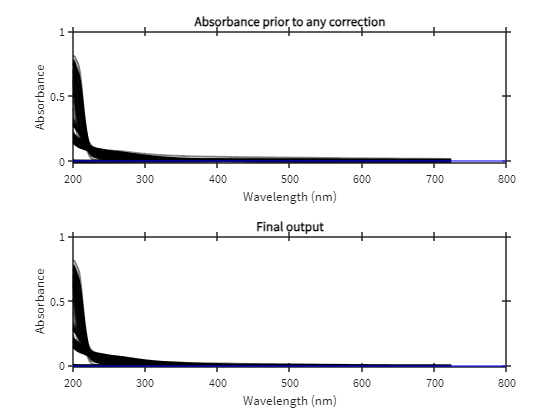

samples.abs=absorbance.abs;
samples.absWave=absorbance.absWave;
samples=tbx.processabsorbance(samples);

clearvars absorbance

That's job done for `absorbance`, we can delete it.

Our next task is to create a blank dataset that corresponds to the samples dataset. I.e. we make sure that the blank subtraction can be done with simple math $X_{\mathrm{blank}\;\mathrm{subtracted}} =X_{\mathrm{Sample}} -X_{\mathrm{Blank}}$. However, that's not how the dataset was collected. We have one blank per day. So we will have to replicate this blank for every sample EEM of the day.

blankNew=drEEMdataset;
for j=1:samples.nSample
    idx=matches(blanks.filelist,char(samples.metadata.blankFile(j)));
    idx=find(idx);
    if not(isempty(idx))
        blankNew.X(j,:,:)=blanks.X(idx,:,:);
        blankNew.filelist{j}=samples.filelist{j};
    else
        disp([char(samples.metadata.sampleFile(j)),'     ',])
    end
end
blankNew.nSample=size(blankNew.X,1);
blankNew.i=(1:blankNew.nSample)';
blankNew.metadata.i=blankNew.i;
blankNew.Ex=blanks.Ex;
blankNew.Em=blanks.Em;
blankNew.nEx=blanks.nEx;
blankNew.nEm=blanks.nEm;
blankNew.validate(blankNew);

This created a new dataset as we wanted. Next, we ensure that we have a blank for every sample and that both datasets are ordered the same.

[samples,blankNew] = tbx.alignsamples(samples,blankNew);

samples: No action necessary. All files between supplied datasets had same names.
blankNew: No action necessary. All files between supplied datasets had same names.


blanks=blankNew;
clearvars -except blanks samples tbx

That's it. Not simple, lot's of sources for errors, lot's of Matlab experience required. The easiest fix for this is to go with the recommendation at the top and store files as triplets with repeating tags.

## Basic processing

Just to demonstrate, we can now carry out the basic data processing with these datasets.

Abs-based IFE correction applied. 


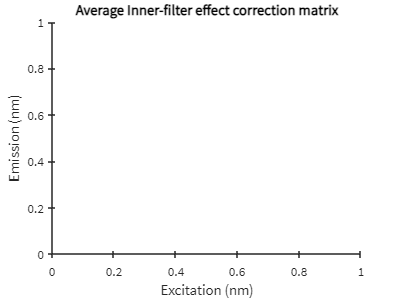

samples=tbx.ifecorrection(samples);

samples=tbx.subtractblanks(samples,blanks);
samples=tbx.ramancalibration(samples,blanks);

Raman normalization wavelength (350) found in EEM data.



% tbx.viewscatter(samples)
load("scatteroptions.mat")
samples=tbx.handlescatter(samples,scatteroptions);
save('CR2013.mat',"samples")

## Spectral correction

The toolbox currently does not ship with a function to carry out spectral corrections. Here we will quickly demonstrate how you can carry out this operation yourself. The dataset loaded here is actually corrected, so I demonstrate this with a dummy vector for the correction spectra.

xcor=readtable("spectral_correction_factors.xlsx",Sheet="xcor");
mcor=readtable("spectral_correction_factors.xlsx",Sheet="mcor");
mcor_i=interp1(mcor.wavelength,mcor.factor,samples.Em);
xcor_i=interp1(xcor.wavelength,xcor.factor,samples.Ex);

This code loads the factors stored in a file. Note that if you don't have headers or they are called something else, you'd have to adopt this code. Next, the factors get interpolated so they match the dataset wavelengths.

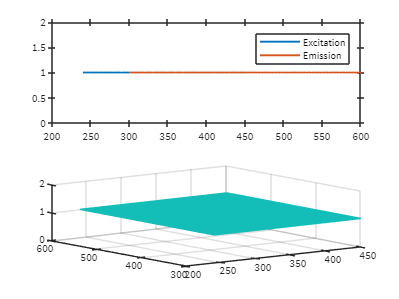

figure
nexttile
plot(samples.Ex,xcor_i,DisplayName='Excitation')
hold on
plot(samples.Em,mcor_i,DisplayName='Emission')
legend
clearvars corfac
corfac(1,:,:)=xcor_i'.*mcor_i;
nexttile
mesh(samples.Ex,samples.Em,squeeze(corfac))

This will make a correction factor EEM (`corfac`) and visualize the vectors, as well as the correction EEM.

samples.X=samples.X.*corfac;
tbx.changestatus(samples);

Error using drEEMtoolbox.changestatus (line 21)
setstatus closed before save & exit button was pushed.

Our last job is to multiply the sample EEMs with the correction EEM and change the status of the dataset to remind ourselves for later that the correction was carried out.